# xBeryllium

#### Basis Functions

Z = 4;
a1s = [70.64859542, 12.92782254, 3.591490662, 1.191983464]

a1s =    70.6486   12.9278    3.5915    1.1920


a2s = [3.072833610, 0.6652025433, 0.2162825386, 0.08306680972];
a = [a1s;a2s];
n = length(a1s);
Norbitals = 2;
sympref('FloatingPointOutput',true);
syms chi1s(x) chi2s(x) chi2(al,x)
chi1s(x) = exp(-a1s*x^2);
Chi1s = formula(chi1s);
chi2s(x) = exp(-a2s*x^2);
Chi2s = formula(chi2s);
Chi = [Chi1s;Chi2s];
chi2(al,x) = exp(-al*x^2);

#### Overlap Matrix


$$S_{pq} = \langle \chi_p|\chi_q\rangle$$


S = zeros(n,n);
for i=1:Norbitals
    for p=1:n
        for q=1:n
            S(p,q) = S(p,q) + int(4*pi*x^2*Chi(i,p)*Chi(i,q),x,0,inf);
        end
    end
end

S;
%Diagonalization
X = zeros(n,n);
[U,s] = eig(S)

U =     0.8859   -0.4492    0.1149    0.0138
   -0.4310   -0.7057    0.5513    0.1106
    0.1677    0.5295    0.7285    0.4011
   -0.0350   -0.1409   -0.3902    0.9092


s =     0.1291         0         0         0
         0    0.7947         0         0
         0         0    6.6712         0
         0         0         0  100.0511


for i=1:n
    X(i,:) = U(i,:)./sqrt(diag(s)');
end
X;
X'*S*X

ans =     1.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000


#### Hamiltonian

$H_{pq} = \langle\chi_p|T| \chi_q\rangle + \langle\chi_p|V| \chi_q\rangle$T

T = zeros(n,n);

for p=1:n
    for q=1:n
        for i=1:Norbitals
            T(p,q) = T(p,q) + 8*pi*(a(i,q)*a(i,p))*int(x^4*Chi(i,p)*Chi(i,q),x,0,inf);
        end
    end
end

T;
V = zeros(n,n);

for p=1:n
    for q=1:n
        for i=1:Norbitals
            V(p,q) = V(p,q) + 4*Z*pi*int(x*Chi(i,p)*Chi(i,q),x,0,inf);
        end
    end
end

V;
H0 = T-V;

#### Direct and Exchange Integrals

%Store all the integrals: cell element pq contains the
%matrix whose elements rs are the integrals at pqrs fixed
l = zeros(n,n);
D_pq = cell(n,n); %Direct term
for p=1:n
    for q=1:n
        l = zeros(n,n);
        for r=1:n
            for s=1:n
                for i=1:Norbitals
                    f = @(r1,r2) 16*pi^2*r1.^2.*r2.^2.*exp(-a(i,p)*r1.^2)...
                        .*exp(-a(i,r)*r2.^2).*abs(r1-r2).*exp(-a(i,q)*r1.^2)...
                        .*exp(-a(i,s)*r2.^2);
                    l(r,s) = l(r,s) + integral2(f,0,inf,0,inf);
                end
            end
        end
        D_pq{p,q} = l;
    end
end

l = zeros(n,n);
E_pq = cell(n,n); %Exchange term (p, s excanged)
for p=1:n
    for q=1:n
        l = zeros(n,n);
        for r=1:n
            for s=1:n
                for i=1:Norbitals
                    f = @(r1,r2) 16*pi^2*r1.^2.*r2.^2.*exp(-a(i,p)*r1.^2)...
                        .*exp(-a(i,r)*r2.^2).*abs(r1-r2).*exp(-a(i,s)*r1.^2)...
                        .*exp(-a(i,q)*r2.^2);
                    l(r,s) = integral2(f,0,inf,0,inf);
                end
            end
        end
        E_pq{p,q} = l;
    end
end

#### Self-Consistent Procedure

F = zeros(n,n); %initialization of Fock matrix
Fx = zeros(n,n); %initialization of transormed Fock matrix (X'FX)
D = zeros(n,n); %initial guess for density matrix
check = 1;
old_eval = 0;
eval = zeros(n);
convergence = 1e-10;
i = 0;

while check>convergence
    i=i+1;                                  % count cicle
    old_eval = eval(1);
    F=FockMatrix(n,Z,D,D_pq,E_pq,H0);       % build Fock matrix
    Fx=X'*F*X;                              % Transoform F matrix
    [Cx,eval_unoredered]=eig(Fx);           % diagonalize Fx
    [eval,perm]=sort(diag(eval_unoredered));% order eigenvalues
    tmp=Cx;
    for k=1:n
        Cx(:,k)=tmp(:,perm(k));             % correspon. evec
    end
    C = X*Cx;                               % basis exp. coef.
    %Normalize eigenvectors C
%     for k=1:n
%         C(:,k)=C(:,k)/norm(C(:,k));
%     end
    D = 2*C(:,1)*C(:,1)';
    check = abs(eval(1)-old_eval);
    eval(1);
end
E = 0.5*sum(D(:).*(H0(:)+F(:)));

#### Final result for Helium

syms Psi(x)
Psi(x)=(C(1,1)*chi2(a(1),x)+C(2,1)*chi2(a(2),x)+C(3,1)*chi2(a(3),x)+C(4,1)*chi2(a(4),x))

$$Psi(x) = 1.4088\,{\mathrm{e}}^{-70.6486\,x^{2}}-0.0067\,{\mathrm{e}}^{-12.9278\,x^{2}}+6.5678e-04\,{\mathrm{e}}^{-0.6652\,x^{2}}+0.1123\,{\mathrm{e}}^{-3.0728\,x^{2}}$$

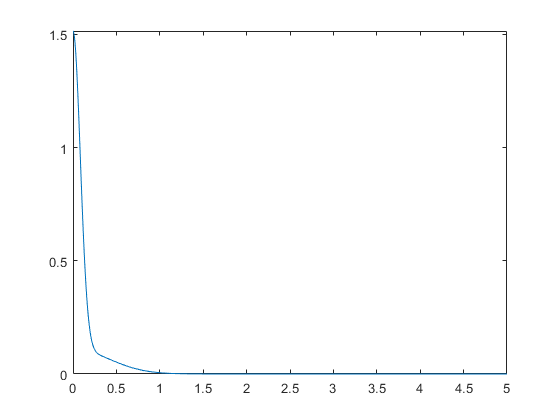

fplot(Psi,[0,5])

function F = FockMatrix(n,Z,P,D_pq,E_pq,H0)
    F = zeros(n,n);
    for p=1:n
        for q=1:n
            F_pq = 0;
            for r=1:n
                for s=1:n
                    F_pq = F_pq + P(r,s)*(D_pq{p,q}(r,s)-0.5*E_pq{p,q}(r,s));
                end
            end
            F(p,q)=F_pq + H0(p,q);
        end
    end
end